# Taller 15

#### Julian David Porras Morales

#### 5/11/2023

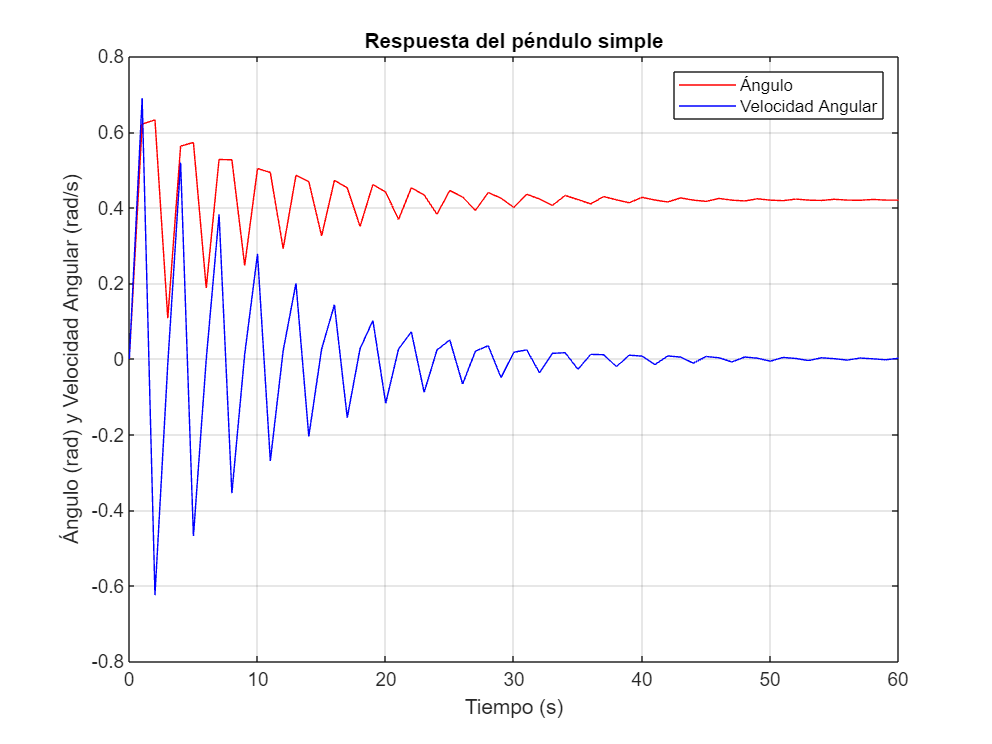

syms x1(t) x2(t)
dx1 = diff(x1(t), t, 1);
dx2 = diff(x2(t), t, 1);
Ts = 1;
tmin = 0;
tmax = 60;
tspan = tmin:Ts:tmax;
m = 1;
l = 2;
g = 9.8;
F = 0.2;
U = 1;
Ci_x1 = 0;
Ci_x2 = 0;
Ci_pendulo = [Ci_x1 Ci_x2];
Tasa_x1 = x2;
Tasa_x2 = -(g / l) * sin(x1) - (F / m) * x2 + (U / m * l);
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2], [x1 x2]);
[tiempo, Salida] = ode45(Funciones_estado, tspan, Ci_pendulo);

% Grafica
figure;
plot(tiempo, Salida(:, 1), 'r', tiempo, Salida(:, 2), 'b');
xlabel('Tiempo (s)');
ylabel('Ángulo (rad) y Velocidad Angular (rad/s)');
legend('Ángulo', 'Velocidad Angular');
title('Respuesta del péndulo simple');
grid on

El valor de u en el que el sistema rotara indefinidamente es de aproximadamente 1.9

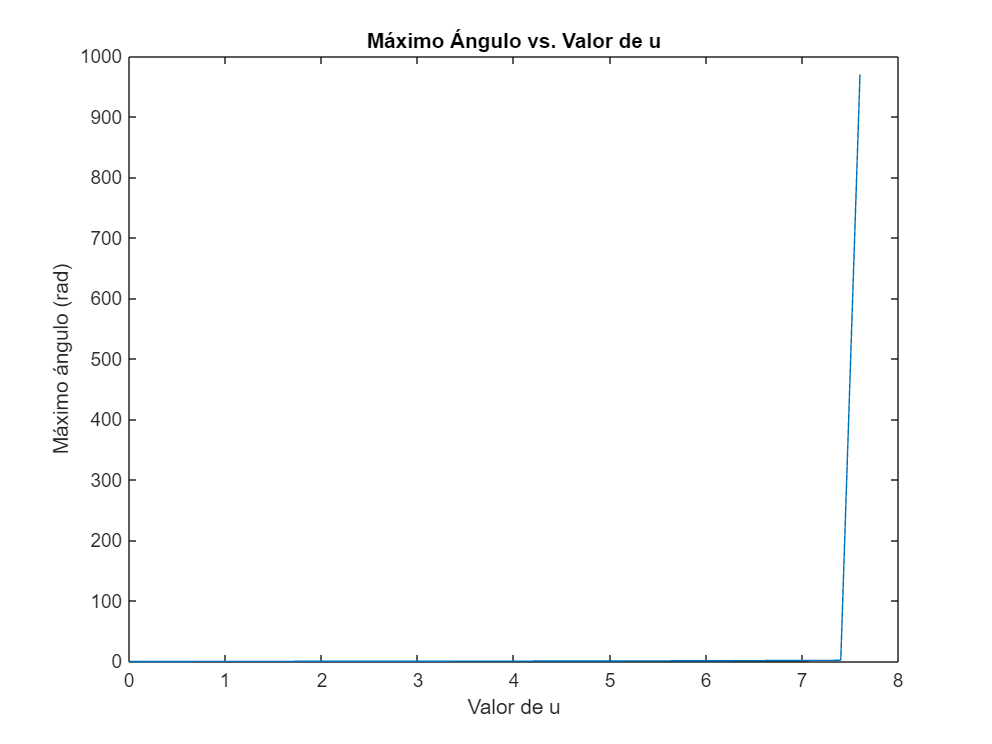

syms x1(t) x2(t)
dx3 = diff(x1(t), t, 1);
dx4 = diff(x2(t), t, 1);
Ts = 1;
tmin = 0;
tmax = 60;
tspan = tmin:Ts:tmax;
m = 1;
l = 2;
g = 9.8;
Ci_x1 = 0;
Ci_x2 = 0;
Ci_pendulo = [Ci_x1 Ci_x2];

% Valores de u 
U_values = 0:0.2:7.6; 

max_theta = zeros(size(U_values));

for i = 1:length(U_values)
    U = U_values(i);
    Tasa_x1 = x2;
    Tasa_x2 = -(g / l) * sin(x1) - (F / m) * x2 + (U / (m * l));
    Funciones_estado = odeFunction([Tasa_x1 Tasa_x2], [x1 x2]);
    [tiempo, Salida] = ode45(Funciones_estado, tspan, Ci_pendulo);

    % valor máximo de θ
    max_theta(i) = max(abs(Salida(:, 1)));
end

% Graficar resultados
figure;
plot(U_values, max_theta);
xlabel('Valor de u');
ylabel('Máximo ángulo (rad)');
title('Máximo Ángulo vs. Valor de u');

3

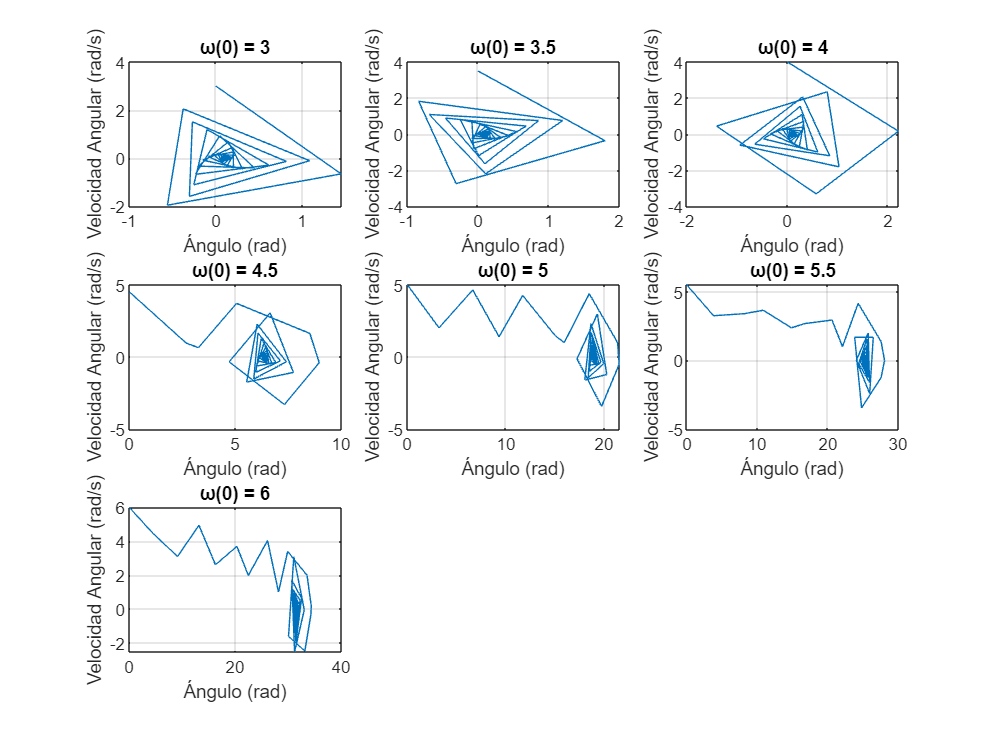

syms x1(t) x2(t)
dx5 = diff(x1(t), t, 1);
dx6 = diff(x2(t), t, 1);
Ts = 1;
tmin = 0;
tmax = 60;
tspan = tmin:Ts:tmax;
m = 1;
l = 2;
g = 9.8;
F = 0.2;
U = 1;
Ci_x1 = 0;
Ci_pendulo = Ci_x1; 
omega_values = 3:0.5:6; % Rango de valores iniciales de velocidad angular

% retrato de fase
figure;

for i = 1:length(omega_values)
    Ci_x2 = omega_values(i);
    Ci_pendulo = [Ci_x1, Ci_x2];
    
    Tasa_x1 = x2;
    Tasa_x2 = -(g / l) * sin(x1) - (F / m) * x2 + (U / (m * l));
    Funciones_estado = odeFunction([Tasa_x1, Tasa_x2], [x1, x2]);
    [tiempo, Salida] = ode45(Funciones_estado, tspan, Ci_pendulo);

    % Grafica retrato de fase
    subplot(3, 3, i);
    plot(Salida(:, 1), Salida(:, 2));
    xlabel('Ángulo (rad)');
    ylabel('Velocidad Angular (rad/s)');
    title(['ω(0) = ', num2str(Ci_x2)]);
    grid on
end

El pendulo da una vuelta cuando omega inicial es 4.5 y da tres vueltas cuando es 5

4

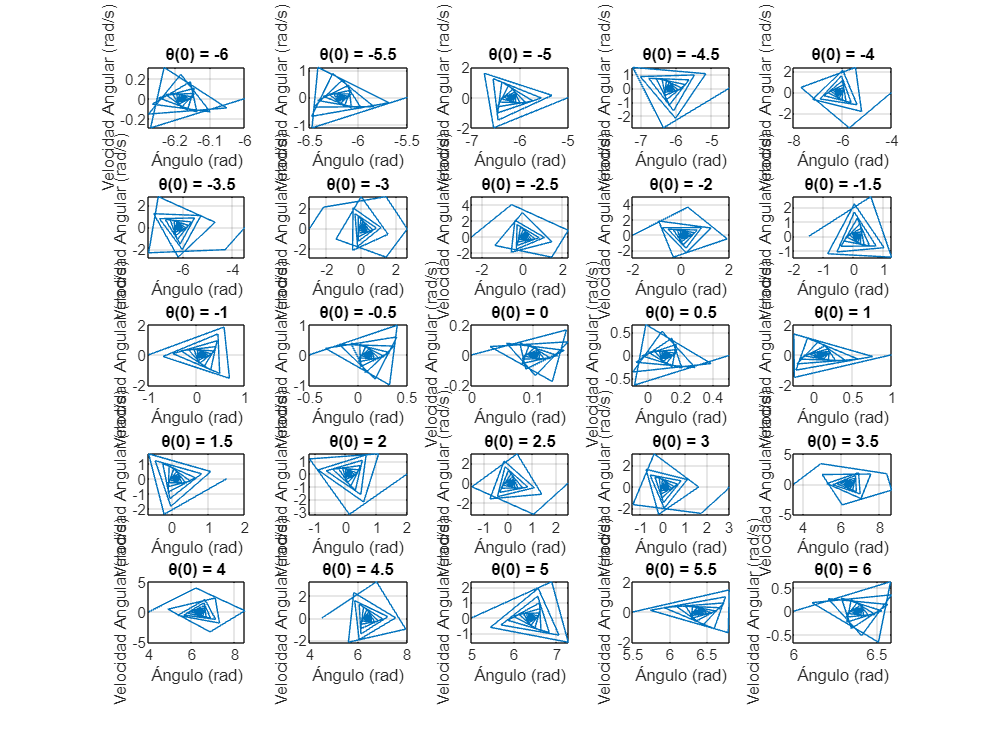

syms x1(t) x2(t)
dx7 = diff(x1(t), t, 1);
dx8 = diff(x2(t), t, 1);
Ts = 1;
tmin = 0;
tmax = 60;
tspan = tmin:Ts:tmax;
m = 1;
l = 2;
g = 9.8;
F = 0.2;
U = 1;
Ci_x2 = 0;
theta_values = -6:0.5:6; % Rango de valores iniciales de posición angular

% figura para el retrato de fase
figure;

for i = 1:length(theta_values)
    Ci_x1 = theta_values(i);
    Ci_pendulo = [Ci_x1, Ci_x2];
    
    Tasa_x1 = x2;
    Tasa_x2 = -(g / l) * sin(x1) - (F / m) * x2 + (U / (m * l));
    Funciones_estado = odeFunction([Tasa_x1, Tasa_x2], [x1, x2]);
    [tiempo, Salida] = ode45(Funciones_estado, tspan, Ci_pendulo);

    % Grafica retrato de fase
    subplot(5, 5, i); 
    plot(Salida(:, 1), Salida(:, 2));
    xlabel('Ángulo (rad)');
    ylabel('Velocidad Angular (rad/s)');
    title(['θ(0) = ', num2str(Ci_x1)]);
    grid on
end

5

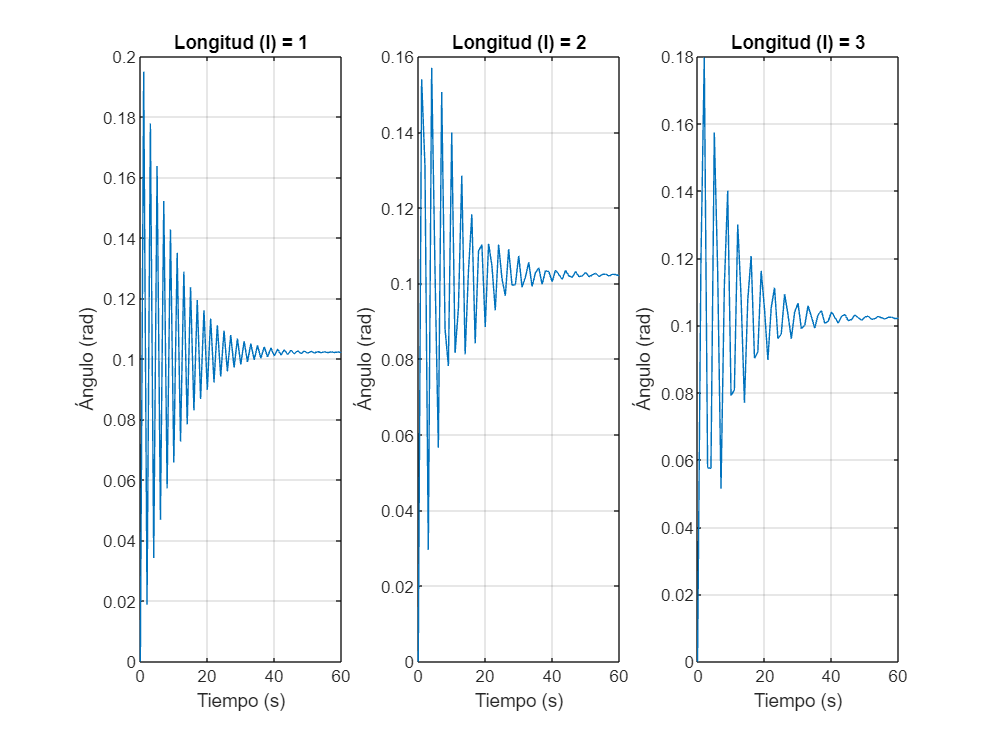

syms x1(t) x2(t)
dx9 = diff(x1(t), t, 1);
dx10 = diff(x2(t), t, 1);
Ts = 1;
tmin = 0;
tmax = 60;
tspan = tmin:Ts:tmax;
m = 1;
g = 9.8;
F = 0.2;
U = 1;
Ci_x1 = 0;
Ci_x2 = 0;
l_values = [1, 2, 3]; % Valores de longitud a probar

% figura para los resultados
figure;

for i = 1:length(l_values)
    l = l_values(i);
    
    Tasa_x1 = x2;
    Tasa_x2 = -(g / l) * sin(x1) - (F / m) * x2 + (U / (m * l));
    Funciones_estado = odeFunction([Tasa_x1, Tasa_x2], [x1, x2]);
    Ci_pendulo = [Ci_x1, Ci_x2];
    [tiempo, Salida] = ode45(Funciones_estado, tspan, Ci_pendulo);

    % Grafica de la respuesta en el tiempo para cada longitud
    subplot(1, 3, i);
    plot(tiempo, Salida(:, 1));
    xlabel('Tiempo (s)');
    ylabel('Ángulo (rad)');
    title(['Longitud (l) = ', num2str(l)]);
    grid on
end

La longitud del péndulo afecta a frecuencia, teniendo una relación inversamente proporcional, ya que a mayor longitud del péndulo menor va a ser su frecuencia.

6

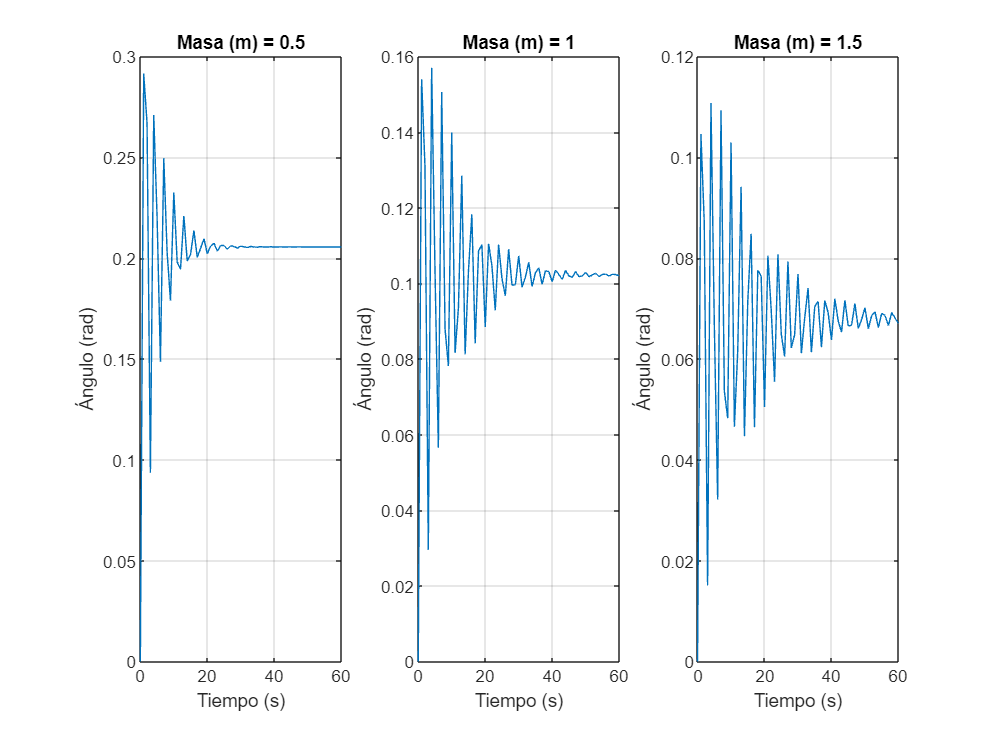

syms x1(t) x2(t)
dx11 = diff(x1(t), t, 1);
dx12 = diff(x2(t), t, 1);
Ts = 1;
tmin = 0;
tmax = 60;
tspan = tmin:Ts:tmax;
l = 2;
g = 9.8;
F = 0.2;
U = 1;
Ci_x1 = 0;
Ci_x2 = 0;
m_values = [0.5, 1, 1.5]; % Valores de masa a probar

% figura para los resultados
figure;

for i = 1:length(m_values)
    m = m_values(i);
    
    Tasa_x1 = x2;
    Tasa_x2 = -(g / l) * sin(x1) - (F / m) * x2 + (U / (m * l));
    Funciones_estado = odeFunction([Tasa_x1, Tasa_x2], [x1, x2]);
    Ci_pendulo = [Ci_x1, Ci_x2];
    [tiempo, Salida] = ode45(Funciones_estado, tspan, Ci_pendulo);

    % Grafica de la respuesta en el tiempo para cada masa
    subplot(1, 3, i);
    plot(tiempo, Salida(:, 1));
    xlabel('Tiempo (s)');
    ylabel('Ángulo (rad)');
    title(['Masa (m) = ', num2str(m)]);
    grid on
end

En las gráficas se puede observar que cuanto mayor sea la masa mayor es el número de oscilaciones de un péndulo.

7

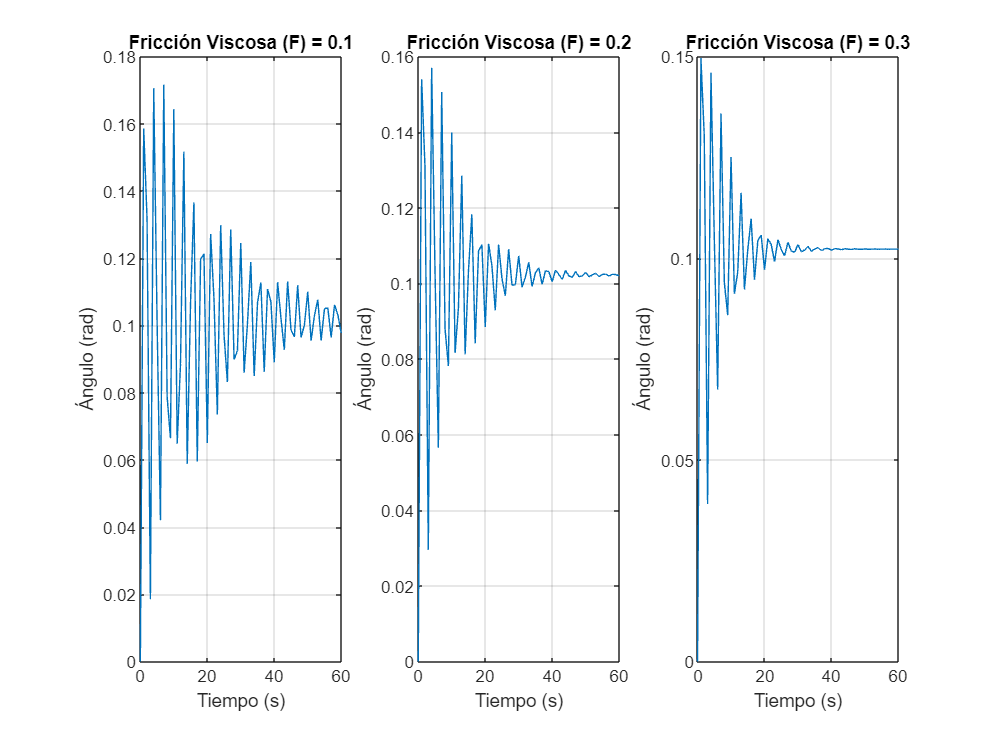

syms x1(t) x2(t)
dx1 = diff(x1(t), t, 1);
dx2 = diff(x2(t), t, 1);
Ts = 1;
tmin = 0;
tmax = 60;
tspan = tmin:Ts:tmax;
m = 1;
l = 2;
g = 9.8;
U = 1;
Ci_x1 = 0;
Ci_x2 = 0;
F_values = [0.1, 0.2, 0.3]; % Valores de fricción viscosa a probar

figure;

for i = 1:length(F_values)
    F = F_values(i);
    
    Tasa_x1 = x2;
    Tasa_x2 = -(g / l) * sin(x1) - (F / m) * x2 + (U / (m * l));
    Funciones_estado = odeFunction([Tasa_x1, Tasa_x2], [x1, x2]);
    Ci_pendulo = [Ci_x1, Ci_x2];
    [tiempo, Salida] = ode45(Funciones_estado, tspan, Ci_pendulo);

    % Grafica de la respuesta en el tiempo para cada valor de fricción viscosa
    subplot(1, length(F_values), i);
    plot(tiempo, Salida(:, 1));
    xlabel('Tiempo (s)');
    ylabel('Ángulo (rad)');
    title(['Fricción Viscosa (F) = ', num2str(F)]);
    grid on
end

De acuerdo a las gráficas podemos concluir que el cambio de fricción cambia la amplitud, entre mayor es la fricción menor es la amplitud y por ende el número de oscilaciones tiende a disminuir también.